usage: teamwork for week 15

author: 黄哲昊 毛晨光 鲁潇阳

date: 2020.6.13

clear all; close all; clc

**1. 求解初值问题**


$$   $$
   \begin{cases}
   \frac{dy}{dt} =\frac{t^2}{y} \\
   y(0)=2,\quad t\in [0,7.0]
   \end{cases}
   $$$$


**   (1) 设置步长**$$h=0.7$$**, 采用前向欧拉算法。**

**   (2) 设置步长**$$h=0.7$$**, 采用Heun方法(即改进的欧拉公式)。**

**   (3) 设置步长**$$h=0.7$$**, 采用经典RK4方法。**

**   (4) 精确解为**$$y=\sqrt{\frac{2x^3}{3}+4}$$**, 请将上述数值计算结果与之比较， 讨论误差。并将结果画在一张图上.**

解：

clear all; close all; clc
f_1 = @(t, y) t.^2./y;
h_1 = 0.7;
t_1 = 0:h_1:7;
y0_1 = 2;
% (1) 前向欧拉算法
y_1_EulerODE = EulerODE(f_1, t_1, y0_1);
% (2) Heun方法(即RK2中alpha=0.5)
y_1_Heun = RK2(f_1, t_1, y0_1, 0.5);
% (3) 经典RK4方法
y_1_RK4 = RK4(f_1, t_1, y0_1);
% (4) 精确解
y_1_check = sqrt(2*t_1.^3./3+4);

% 计算数值方法和精确解的误差
E_1_EulerODE = abs(y_1_EulerODE - y_1_check);
E_1_Heun = abs(y_1_Heun - y_1_check);
E_1_RK4 = abs(y_1_RK4 - y_1_check);

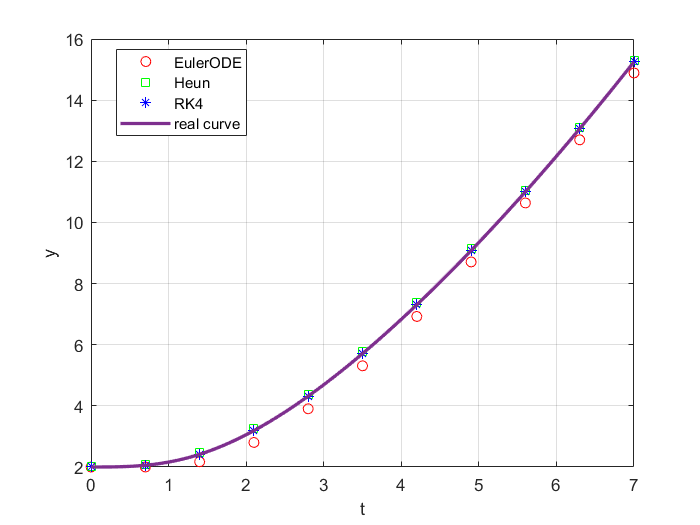

% 做出函数图像
plot(t_1, y_1_EulerODE, 'ro', t_1, y_1_Heun, 'gs', t_1, y_1_RK4, 'b*')
hold on
plot(0:0.1:7, sqrt(2*(0:0.1:7).^3./3+4), 'LineWidth', 2)
grid on
xlabel('t')
ylabel('y')
hold off
legend("EulerODE", "Heun", "RK4", "real curve", 'Location', "best")

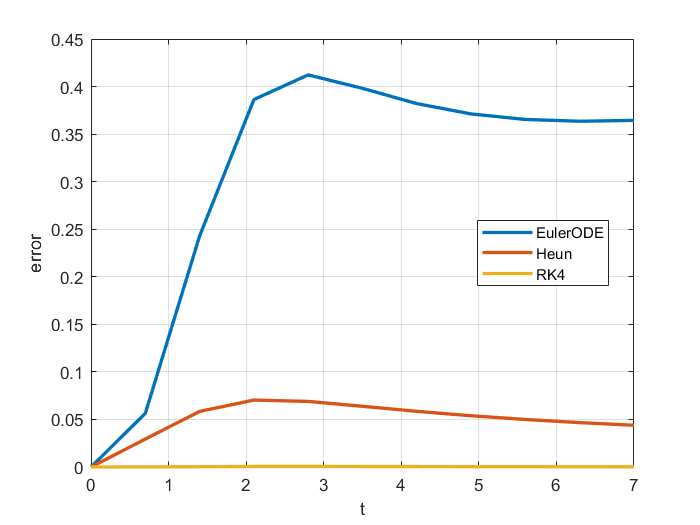

% 做出三种方法的误差图像
plot(t_1, E_1_EulerODE, t_1, E_1_Heun, t_1, E_1_RK4, 'LineWidth', 2)
grid on
xlabel('t')
ylabel('error')
legend("EulerODE", "Heun", "RK4", 'Location', "best")

从图中可以直观的看出前向欧拉方法的误差最大，Heun方法次之，经典RK4方法的误差最小。

**2. 求解初值问题**


$$   $$
   \begin{cases}
   \frac{dy}{dx} =x-\frac{xy}{2} \\
   y(1)=1,\quad x\in [1,5]
   \end{cases}
   $$$$


**   (1) 设置步长**$$h=0.4$$**, 采用前向欧拉算法。**

**   (2) 设置步长**$$h=0.4$$**, 采用Heun方法(即改进的欧拉公式)。**

**   (3) 设置步长**$$h=0.4$$**, 采用经典RK4方法。**

**   (4) 精确解为**$$y=2-e^{\frac{1-x^2}{4}}$$**, 请将上述数值计算结果与之比较， 讨论误差。并将结果画在一张图上.**

解：

clear all; close all; clc
f_2 = @(x, y) x - x.*y/2;
h_2 = 0.4;
x_2 = 1:h_2:5;
y0_2 = 1;
% (1) 前向欧拉算法
y_2_EulerODE = EulerODE(f_2, x_2, y0_2);
% (2) Heun方法(即RK2中alpha=0.5)
y_2_Heun = RK2(f_2, x_2, y0_2, 0.5);
% (3) 经典RK4方法
y_2_RK4 = RK4(f_2, x_2, y0_2);
% (4) 精确解
y_2_check = 2-exp((1-x_2.^2)/4);

% 计算数值方法和精确解的误差
E_2_EulerODE = abs(y_2_EulerODE - y_2_check);
E_2_Heun = abs(y_2_Heun - y_2_check);
E_2_RK4 = abs(y_2_RK4 - y_2_check);

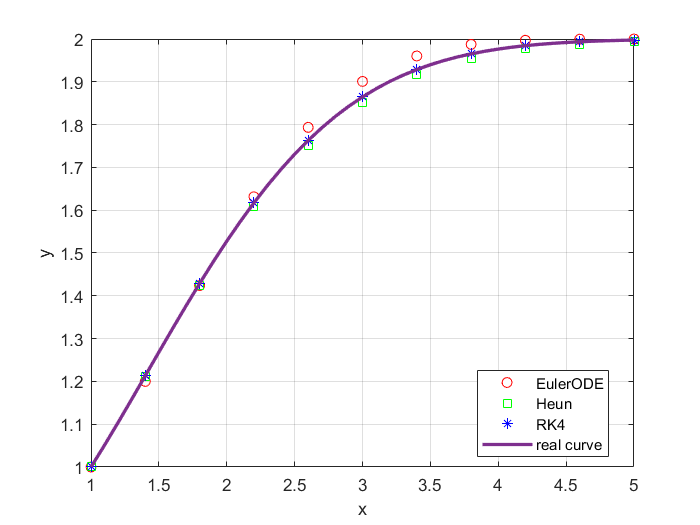

% 做出函数图像
plot(x_2, y_2_EulerODE, 'ro', x_2, y_2_Heun, 'gs', x_2, y_2_RK4, 'b*')
hold on
plot(1:0.1:5, 2-exp((1-(1:0.1:5).^2)/4), 'LineWidth', 2)
grid on
xlabel('x')
ylabel('y')
hold off
legend("EulerODE", "Heun", "RK4", "real curve", 'Location', "best")

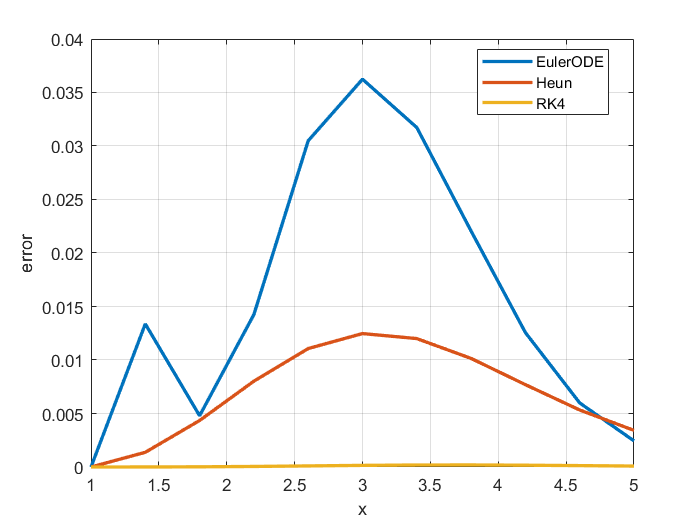

% 做出三种方法的误差图像
plot(x_2, E_2_EulerODE, x_2, E_2_Heun, x_2, E_2_RK4, 'LineWidth', 2)
grid on
xlabel('x')
ylabel('error')
legend("EulerODE", "Heun", "RK4", 'Location', "best")

从误差曲线中可以看出，仍然是前向欧拉算法的误差最大，Heun方法的误差次之，经典RK方法的误差最小。

**3. 求解初值问题**


$$   $$
   \begin{cases}
   \frac{dy}{dt} =y+t^3\\
   y(0)=1,\quad x\in [0,5]
   \end{cases}
   $$$$


**   (1) 设置步长**$$h=0.5$$**, 采用前向欧拉算法。**

**   (2) 设置步长**$$h=0.5$$**, 采用中心公式。**

**   (3) 设置步长**$$h=0.5$$**, 采用经典RK4方法。**

**   (4) 精确解为**$$y=7e^t-t^3-3t^2-6t-6$$**, 请将上述数值计算结果与之比较， 讨论误差。并将结果画在一张图上.**

解：

clear all; close all; clc
f_3 = @(t, y) y + t.^3;
h_3 = 0.5;
t_3 = 0:h_3:5;
y0_3 = 1;
% (1) 前向欧拉算法
y_3_EulerODE = EulerODE(f_3, t_3, y0_3);
% (2) 中心方法(即RK2中alpha=0)
y_3_Heun = RK2(f_3, t_3, y0_3, 0);
% (3) 经典RK4方法
y_3_RK4 = RK4(f_3, t_3, y0_3);
% (4) 精确解
y_3_check = 7.*exp(t_3) - t_3.^3 - 3*t_3.^2 - 6*t_3 - 6;

% 计算数值方法和精确解的误差
E_3_EulerODE = abs(y_3_EulerODE - y_3_check);
E_3_Heun = abs(y_3_Heun - y_3_check);
E_3_RK4 = abs(y_3_RK4 - y_3_check);

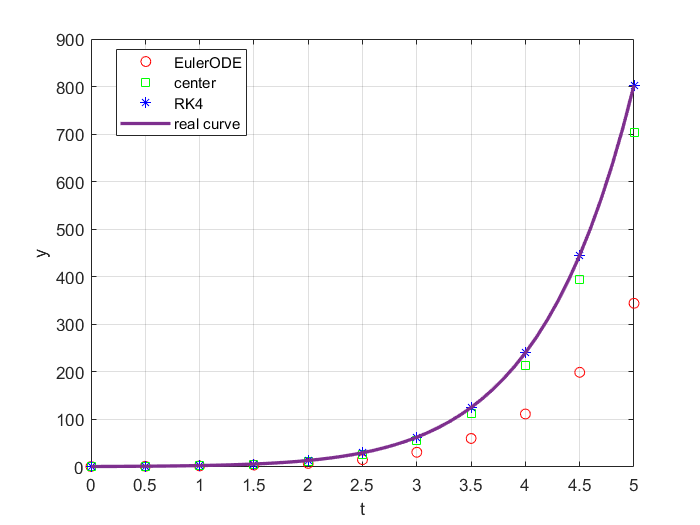

% 做出函数图像
plot(t_3, y_3_EulerODE, 'ro', t_3, y_3_Heun, 'gs', t_3, y_3_RK4, 'b*')
hold on
plot(0:0.1:5, 7.*exp(0:0.1:5) - (0:0.1:5).^3 - 3*(0:0.1:5).^2 - 6*(0:0.1:5) - 6, 'LineWidth', 2)
grid on
xlabel('t')
ylabel('y')
hold off
legend("EulerODE", "center", "RK4", "real curve", 'Location', "best")

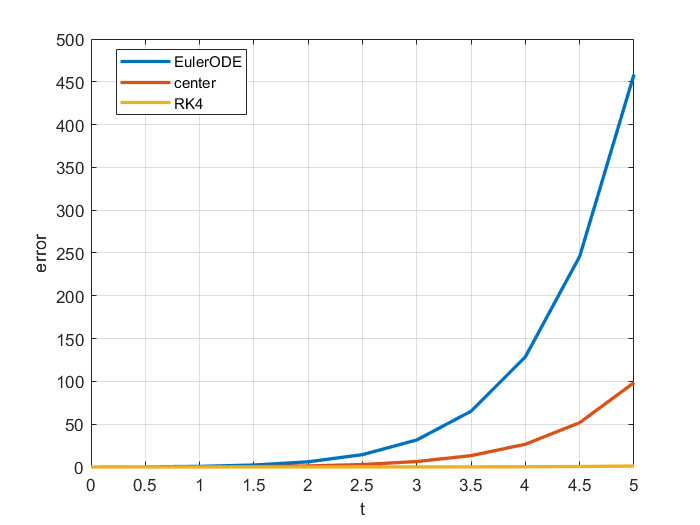

% 做出三种方法的误差图像
plot(t_3, E_3_EulerODE, t_3, E_3_Heun, t_3, E_3_RK4, 'LineWidth', 2)
grid on
xlabel('t')
ylabel('error')
legend("EulerODE", "center", "RK4", 'Location', "best")

从误差曲线中可以看出，前向欧拉算法的误差随$t$的增大增长最大，中心方法的误差次之，经典RK方法的误差最小。

**4. 求解变系数的一阶微分方程**


$$   $$\begin{cases}
   y^\prime(t) + f(t)y(t) = g(t)\\
   y(1) = 1,\quad t\in [1,5]
   \end{cases}$$$$


**   已知**$$f(t)$$**在时间节点`ft`的函数值为`f`. **$ $g(t)$$**在时间节点`gt`的函数值为`g`**

clear all; close all; clc
ft = linspace(0,5,25);
f = ft.^2 - ft - 3;

gt = linspace(1,6,25);
g = 3 * sin(gt - 0.25);

**    (1) 设置步长**$$h=0.1$$**, 采用RK2的中心公式， 计算**$$y(t)$$**的近似值。**

**   (2) 设置步长**$$h=0.1$$**, 采用经典RK4公式， 计算**$$y(t)$$**的近似值, 并与(1)题结果比较。请将结果画在一张图上。**

**   提示： 可调用matlab的内置函数`interp1`对**$$f(t)$$**与**$$g(t)$$**进行插值。**

解：

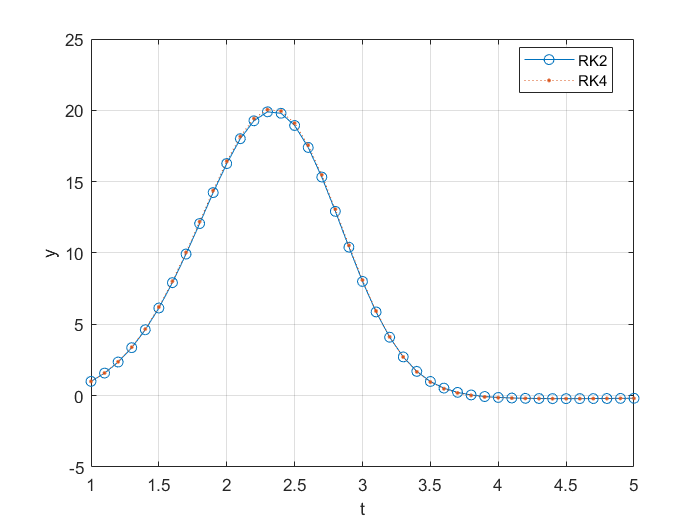

F_4 = @(t) interp1(ft, f, t);
G_4 = @(t) interp1(gt, g, t);
f_4 = @(t, y) G_4(t) - F_4(t).*y;
h_4 = 0.1;
t_4 = 1:h_4:5;
y0_4 = 1;
% (1) RK2中心公式(alpha=0)
y_4_RK2 = RK2(f_4, t_4, y0_4, 0);
% (2) 经典RK4公式
y_4_RK4 = RK4(f_4, t_4, y0_4);

% 作出两个方法的结果图像
plot(t_4, y_4_RK2, 'o-', t_4, y_4_RK4, ':.');
xlabel("t")
ylabel("y")
grid on
legend("RK2", "RK4", 'Location', "best")

两种方法得到的函数图像基本相同，在$[1.5, 3]$的区间内两种方法得到近似值有些偏差。

**5. 误差函数**$erf(x)$**由以下积分形式定义**


$$    $$
    \text{erf}(x) = \frac{2}{\sqrt{\pi}}\int_0^x e^{-x^2}dx
    $$$$


**    也可以通过求解以下常微分方程求得近似值**


$$    $$
    \begin{cases}
    y^\prime =\frac{2}{\sqrt{\pi}}e^{-x^2}\\
    y(0)=0
    \end{cases}
    $$$$


**    选择合适的步长，采用RK4方法在**$$0 \le  x \le  2$$**上求解，并与matlab内置函数`erf(x)`比较结果.**

解：

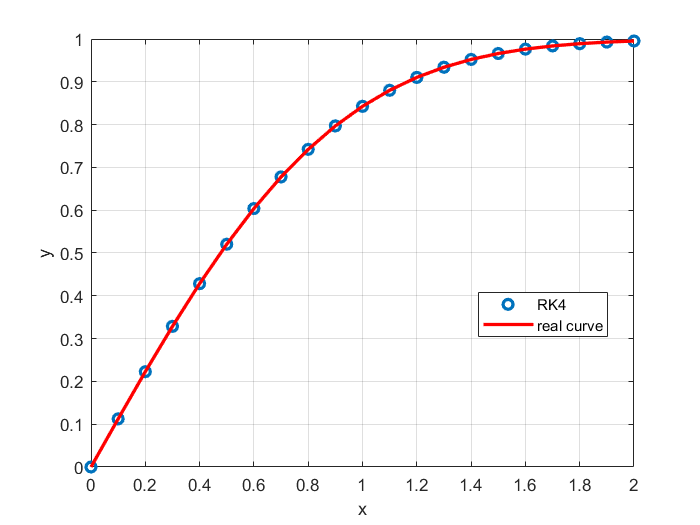

clear all; close all; clc
f_5 = @(x, y) 2*exp(-x.^2)/sqrt(pi);
h_5 = 0.1;
x_5 = 0:h_5:2;
y0_5 = 0;
% 采用经典RK4方法求解
y_5_RK4 = RK4(f_5, x_5, y0_5);
% matlab内置函数 erf(x)
y_5_check = erf(x_5);
% 计算误差
E_5_RK4 = abs(y_5_check - y_5_RK4)./y_5_check;
% 作出近似值和精确值的比较
plot(x_5, y_5_RK4, 'o', x_5, y_5_check, 'r-', 'LineWidth', 2);
xlabel("x")
ylabel("y")
grid on
legend("RK4", "real curve", 'Location', "best")

RK4方法迭代得到的近似值与erf(x)精确值基本相等。

**6. 请将以下2阶常微分方程改写成两个一阶常微分方程组**


$$    $$
    \frac{d^2y}{dt^2}+5\left(\frac{dy}{dt}\right)^2-6y+e^{\sin t}=0
    $$$$


解：


$$\pmatrix{y_1 \cr y_2} = \pmatrix{y \cr y'}$$



$$\frac{d}{dt}\pmatrix{y_1 \cr y_2} = \pmatrix{y_2 \cr 6y_1-e^{sin(t)} - 5y_2^2}$$


**7. 请将以下两个2阶常微分方程改写成四个一阶常微分方程组**


$$
     \frac{d^2x}{dt^2}=-\frac{\gamma}{m}\left(\frac{dx}{dt}\right)\sqrt{\left(\frac{dx}{dt}\right)^2+\left(\frac{dy}{dt}\right)^2}\\
    \frac{d^2y}{dt^2}=-g-\frac{\gamma}{m}\left(\frac{dy}{dt}\right)\sqrt{\left(\frac{dx}{dt}\right)^2+\left(\frac{dy}{dt}\right)^2}$$


解：


$$\pmatrix{x_1 \cr  x_2 \cr y_1 \cr y_2} = \pmatrix{x \cr x' \cr y \cr y'}$$



$$\frac{d}{dt}\pmatrix{x_1 \cr  x_2 \cr y_1 \cr y_2} = \pmatrix{x_2 \cr -\frac{\gamma}{m}x_2 \sqrt{(x_2)^2+(y_2)^2} \cr y_2 \cr -g-\frac{\gamma}{m}y_2 \sqrt{(x_2)^2+(y_2)^2}}$$


*************************************************functions******************************************

前向欧拉算法

function y = EulerODE(f,x,y0)
%
% EulerODE uses Euler's method to solve a first-order
% ODE given in the form y' = f(x,y) subject to initial
% condition y0.
%
% y = EulerODE(f,x,y0) where
%
% f is an inline function representing f(x,y),
% x is a vector representing the mesh points,
% y0 is a scalar representing the initial value of y,
%
% y is the vector of solution estimates at the mesh
% points.
%
% Ramin S. Esfandiari, Numerical Methods for Engineers and Scientists Using
% Matlab,
% Section 7.1 p.331
%
y = zeros(1,length(x));
y(1) = y0; h = x(2) - x(1);
for n = 1:length(x) - 1
    y(n+1) = y(n) + h*f(x(n),y(n));
end
end

RK2方法


$$    $$
    \begin{cases}
    \alpha + \beta=1 \\
    \beta q= \frac 12
    \end{cases}
    $$$$


function y = RK2(f,x,y0,alpha)
    beta = 1 - alpha;
    q = 0.5/beta;
    y = zeros(1, length(x));
    y(1) = y0;
    h = x(2) - x(1);
    for j = 1:length(x) - 1
        k1 = h*f(x(j),y(j));
        k2 = h*f(x(j) + q*h,y(j) + q*k1);
        y(j+1) = y(j) + alpha * k1 + beta * k2;
    end
end

经典龙格-库塔法RK4

function y = RK4(f,x,y0)
%
% RK4 uses the classical RK4 method to solve a first-
% order ODE given in the form y' = f(x,y) subject to
% initial condition y0.
%
% y = RK4(f,x,y0) where
%
% f is an inline function representing f(x,y),
% x is a vector representing the mesh points,
% y0 is a scalar representing the initial value of y,
%
% y is the vector of solution estimates at the mesh
% points.
%
% Ramin S. Esfandiari, Numerical Methods for Engineers and Scientists Using
% Matlab,
% Section 7.3.3.1 p.347
%
y = zeros(1,length(x));
y(1) = y0; h = x(2) - x(1);
for n = 1:length(x) - 1
    k1 = f(x(n),y(n));
    k2 = f(x(n) + h/2,y(n) + h*k1/2);
    k3 = f(x(n) + h/2,y(n) + h*k2/2);
    k4 = f(x(n) + h,y(n) + h*k3);
    y(n+1) = y(n) + h*(k1 + 2*k2 + 2*k3 + k4)/6;
end
end